#  Local Basis Function Representations of Thermodynamic Surfaces 

# by J.M. Brown

This script performs the calculations associated with the section titled: 

##                 **Representation and  Modification of IAPWS using Local Basis Functions** 

These calculations extend the demonstration of the utility of Local Basis Functions (LBF) over a large regime of pressure (to 100 GPa) and temperature (to >10,000 K). This illustrates the "local" nature of the representations.  The behavior of an equation of state can be modified in one PT regime without impacting the representation in another. Furthermore, the re-parameterizations of properties  (ie., changing which state variables are independent) is demonstrated.

The following is an outline of calculations provided by this script:

- In section 1, a  LBF  representation for Gibbs energy based on IAPWS-95 is created using function "spgft". Since IAPWS is parameterized as Helmholz energy (function of pressure and volume) the evaluation of thermodynamic properties as a function of pressure and temperature is computationally slow. With IAPWS re-parameterized as Gibbs energy (function of P and T), the time required to evaluate thermodynamic properties is reduced.

- In Section 2, the LBF version is tested against the original IAPWS formulation

- In Section 3, the ability (over a very wide range of pressures and temperatures) to convert measured sound speeds (using function "eqst") into a description of densities and specific heats is tested. The resulting properties are then turned into a LBF representation for Gibbs energy (using "spgft").   The resulting EOS is shown to be in agreement with the base EOS - as expected since IAPWS-95 was the source of the sound speeds.

- In Section 4, the base EOS (IAPWS-95) is modified to better fit high pressure measurements of sound speeds and the Hugoniot.  The result is a LBF representation for Gibbs energy that exactly matches IAPWS below 1 GPa while deviating appropriately from IAPWS at higher pressure and temperatures to match available experimental measurements.

Key ideas to consider:

- The reference EOS (IAPWS-95) was designed as a comprehensive model that can be evaluated over a range of pressures extending to greater than 100 GPa and to temperatures greater than 10,000 K.  However, the majority of measurements that constrain the representation lie in a pressure regime below 100 MPa and temperatures below 1000 K where water exhibits large variability in properites. Any numerical framework needs to be adequately flexible to accomodate large variations in predicted properties at low pressure while remaining well behaved at high P and T. In order to cover the wide range of Pand T, "data" and "control points" are logarithmically distributed. Thus, the LBF representations have a non-uniform distributions of  intervals.

- There are trade-offs in the "size" of a model (number of model parameters) and the accuracy of predicted thermodynamic properties. The following calculations match properties at the part-per-million (ppm) level.  Such precision is not always required and substantially smaller models can predict properties at the level of reasonable experimental uncertainty. However, even "large" models are easily handled by current generation computers.

- Individuals using these scripts should modify parameters associated with the calculations.  In particular, explore the impact of changing model "size" (try varying the number of control points), and results obtained with changes in damping, normalization, and weighting.

- Thermodynamic properties vary dramatically near $T_c$. Creating an accurate representationin this regime is challenging. Since near $T_c$  is not the focus of the present effort to determine representations for an extended regime of P and T, the region between 500 K and 900 K for pressures less than 90 MPa is excluded. 

SECTION 1

In this section a LBF representation for Gibbs energy (function of pressure and temperature) is constructed that represents IAPWS extending to 100 GPa and to 15000 K. This follows the process that was used to construct the representation that is coded into the function "fnIAPWSval". 

An input grid of predictions based on IAPWS is required. The code to do this (using function "IAPWS95") is given below but requires considerable time and is commented out. To facilitate use of this script, a file is provided with pre-calculated values.

warning off  % warnings emerging from the following calculations are 
%            generally distracting while typically not being an issue
load IAPWS_grids % load the pre-computed data used as input to spgft
% for convenience set local variables based on the precomputed values:
P=IAPWS_TPa.P;
T=IAPWS_TPa.T;
rho=IAPWS_TPa.rho;
vel=IAPWS_TPa.vel;
mask=IAPWS_TPa.mask;
Cp=IAPWS_TPa.Cp;
G=IAPWS_TPa.G;
% The code to obtain these points (commented out to speed execution):
% results=IAPWS95({P,T},'P'); 
% rho=results.rho;
% vel=results.vel;
% Cp=results.Cp;
% G=results.G;

 Chose the region to include in the LBF representation:

idp=find(P<=1e5);  % consider only pressures to 100 GPa
idt=find(T<1.5e4); % consider only temperatures less than 15,000K

Rename  the chosen subset of P and T 

PTf={P(idp),T(idt)}; 
Gf=G(idp,idt);
rhof=rho(idp,idt);
Cpf=Cp(idp,idt);
velf=vel(idp,idt);

IAPWS-95 does not give accurate results in "non-physical" regions (the low temperature and high pressure regime of ice stability).  The solution of the inverse problem for the local basis functions requires that portions of the PT grid be masked off. An array named "mask" consists of ones or NaN's in the  non-physical regions. The function mk_mask4Gspline returns "mask" with unphysical areas marked with NaN's.  The near $T_c$ region is also masked.

mask=mk_mask4Gspline(PTf); 

Set up the calculation for the inverse problem by setting  options for spgft. Since control points are not specified, every data point is used as a control point. Thus, the damping factors for regularization are set to small values.  Note that regularization is still needed since otherwise the inverse problem would be rank deficit as a result of the masked-off regions. Both weights and damping were manually adjusted to improve the misfit.

clear optionsG  % to insure that an earlier version does not carry over 
%                  unintended options
 optionsG.normflg=1; % by setting this variable, all quantities in the 
 %                        inverse problem are appropriately normalized
optionsG.weight=[5e6 8e3];  % these weight density and Cp relative to 
%                                G and were found by trial and error to
%                                  give an appropriate result
optionsG.lam=5e-6*[1 1]; % damping in P and T for the regularization of 
%                 the fit - for normalized arrays, 1 is a natural choice
optionsG.mask=mask;

Here is the calculation of the LBF representation using function spgft. For some choices of parameters, a warning message that the solution is "Rank Deficient"  may appear.  This is a problem only if the resulting EOS is not adequately representing data.

 tic
 sp_G=spgft(PTf,Gf,rhof,Cpf,optionsG);  
 toc

Elapsed time is 24.433236 seconds.


Test the results 

results=fnGval(sp_G,PTf); 
rhoc=results.rho;
velc=results.vel;
Gc=results.G;
Cpc=results.Cp;

devsvel=real(1e6*(velc-velf)./velc);
devsrho=real(1e6*(rhoc-rhof)./rhoc);
devsCp=real(1e6*(Cpc-Cpf)./Cpc);
id=find(not(isnan(mask)) & isfinite(devsvel));
devs=sum(abs([devsrho(id);devsCp(id);devsvel(id)]));

results2=fnIAPWSval(PTf); % this is called to get a mask appropriate for display
mask=results2.mask;
Pmax=PTf{1}(end);
Tmax=PTf{2}(end);


Below here deviations between the LBF representation for Gibbs energy are compared to the original IAPWS-95 formulation.  First comparisons are made in the low pressure and temperature region. Then deviations are shown over the entire range. The scales are in parts-per-million.  Most points differ by less than 1 ppm. Slightly larger errors can be seen at edges.

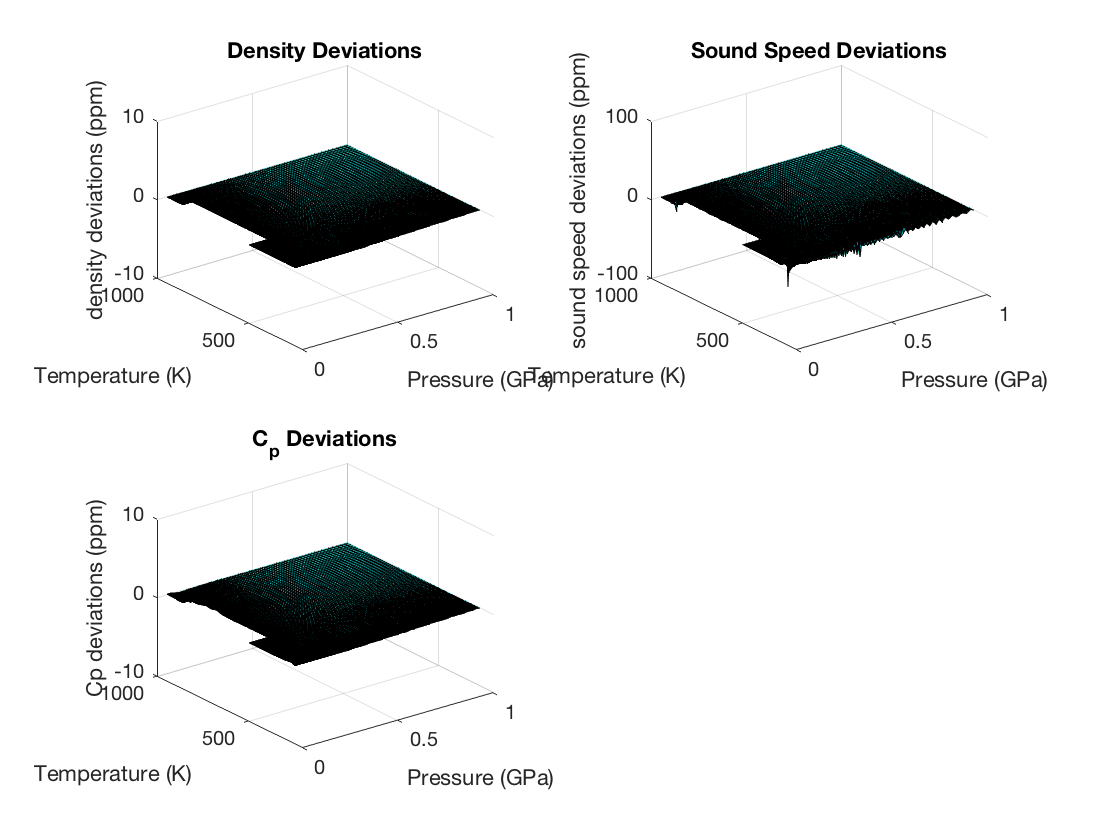

subplot(111)
subplot(221)
therm_surf(PTf,eps+devsrho,mask,'density deviations (ppm)',[0 1e3  200 1000 -10 10])
title('Density Deviations')
subplot(222)
therm_surf(PTf,eps+devsvel,mask,'sound speed deviations (ppm)',[0 1e3  200 1000 -1e2 1e2])
title('Sound Speed Deviations')
subplot(223)
therm_surf(PTf,eps+devsCp,mask,'Cp deviations (ppm)',[0 1e3  200 1000 -10 10])
title('C_p Deviations')

Deviations of LBF-predicted properties from IAPWS in ppm in the low pressure regime.  Note the excluded region around $T_c$ and the region of ice stability at low temperatures and higher pressures. Properties are predicted to better than ppm-level except near the low T edge where errors in sound speed are a few 10's of ppm.

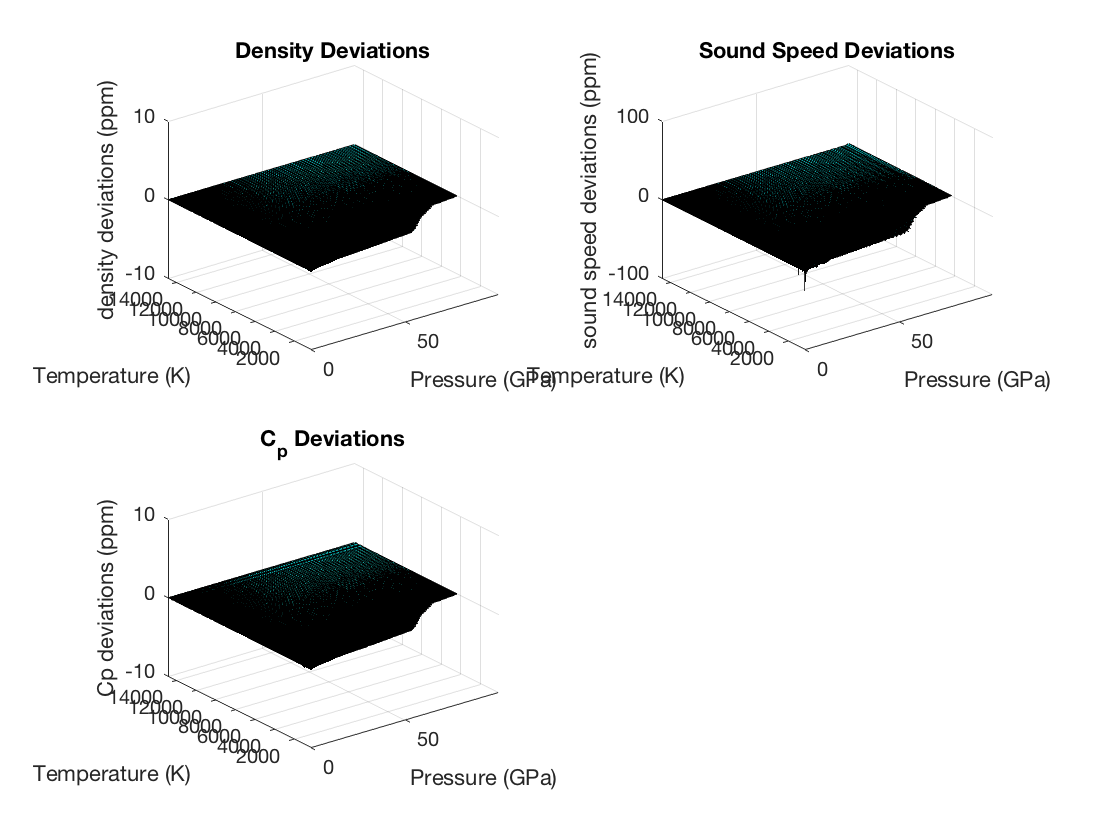

subplot(221)
therm_surf(PTf,eps+devsrho,mask,'density deviations (ppm)',[0 Pmax  200 Tmax -10 10])
title('Density Deviations')
subplot(222)
therm_surf(PTf,eps+real(devsvel),mask,'sound speed deviations (ppm)',[0 Pmax 200 Tmax -1e2 1e2])
title('Sound Speed Deviations')
subplot(223)
therm_surf(PTf,eps+devsCp,mask,'Cp deviations (ppm)',[0 Pmax 200 Tmax -10 10])
title('C_p Deviations')

Deviations of LBF-predicted properties from IAPWS in ppm over the entire range of pressure (100 GPa) and temperature (15,000 K).  Note that the excluded region around $T_c$ is not visible at this scale.  The region of ice stability takes out an increasing regime of temperatures at higher pressures. All properties are predicted to  ppm-level or better over the entire range.

SECTION TWO 

The original formulations for IAPWS-95  is Helmholz energy as a function of temperature and volume. To evaluate properties at a  given pressure-temeprature (P-T) point, a costly (CPU-intensive) search is required to find the volume that correctly predicts the specified pressure. In contrast, the LBF version is re-parameterized to be a function of pressure and temperature which results in faster execution.  Additional efficiencies warrant consideration.  Splines can be equivalently parameterized either in b-form or pp-form (peicewise polynomials). The b-form is efficient for evaluations of gridded input while the pp-form is better suited to evaluations at scattered data sites. Conversion between forms is straightforward and in either case a model consists of a collection of parameters for Gibbs energy and its derivatives. 

In this section, the LBF representation for Gibbs energy is pre-prepared as b-form and pp-form coefficients.  An data set is evaluated both as scattered data and as gridded data.  The execution times for these evaluations is then compared with the time required for evaluations using the original formulation.


% define the range of P and T to test
Trange=[300 1.5e4];
Prange=[0.1 1e5];
nT=100;
nP=500;
P=linspace(Prange(1),Prange(2),nP);
T=linspace(Trange(1),Trange(2),nT);
% assemble data set as a grid and create a cell version
[Pm,Tm]=ndgrid(P,T);
PT={P,T};

Calculate thermodynamic values using the LBF representation "fnIAPWSval"

resultsI=fnIAPWSval(PT);
rhoI=resultsI.rho;
velI=resultsI.vel;
CpI=resultsI.Cp;
mask=resultsI.mask;
%some of the points will be in the excluded regions - find indeces
%   for points in the valid regime of P and T
id=find(not(isnan(mask)));
id=id(:);  % convert the matrix of indeces to a list

Create "scattered data input" using only points in the valid range of the model

PTs=[Pm(id) Tm(id)];

Load the LBF representation and prepare sp and pp versions of the model coefficients.  These model parameters do not change  and thus can be set once in any numerical problem

load IAPWS_sp_strct

convert b-form coefficients to pp-form and determine the derivative parameters

pp=fn2fm(sp_IAPWS,'pp');
ppd2P=fnder(pp,[ 2 0]);
ppd2T =  fnder(pp,[0 2]);
ppd1P  =  fnder(pp,[1 0]);
ppdPT =  fnder(pp,[1 1]);

Determine the derivative parameters for the b-form representation

spd2P=fnder(sp_IAPWS,[ 2 0]);
spd2T =  fnder(sp_IAPWS,[0 2]);
spd1P  =  fnder(sp_IAPWS,[1 0]);
spdPT =  fnder(sp_IAPWS,[1 1]);


Time the evaluation of the pp-form using "scattered data" input 

tic 
    d2T=fnval(ppd2T,PTs')';
    d1P=fnval(ppd1P,PTs')';
    dPT=fnval(ppdPT,PTs')';
    d2P=fnval(ppd2P,PTs')';
    CpI=-d2T.*PTs(:,2);
    velI=sqrt(d1P.^2./(dPT.^2./d2T - d2P)); % MPa-Pa units conversion cancels
    rhoI=1e6*d1P.^(-1);  % 1e6 for MPa to Pa
t_LBFpp=toc

t_LBFpp = 0.4099

Now do the same calculation using the b-form

tic 
    d2T=fnval(spd2T,PT);
    d1P=fnval(spd1P,PT);
    dPT=fnval(spdPT,PT);
    d2P=fnval(spd2P,PT);
    CpI=-d2T(id).*Tm(id);
    velI=sqrt(d1P(id).^2./(dPT(id).^2./d2T(id) - d2P(id))); % MPa-Pa units conversion cancels
    rhoI=1e6*d1P(id).^(-1);  % 1e6 for MPa to Pa
t_LBFsp=toc

t_LBFsp = 0.1433

Per output above, the sp-form is about a factor of two faster than the pp-form.  Below the work space is "cleaned up" by deleting all the model parameters

clear sp_IAPWS spd2T spd2P spd1P spdPT ppd2T ppd2P ppd1P ppdPT

Evaluate thermodynamic properties using the full IAPWS representation

tic
resultsII=IAPWS95(PTs,'P');
t_IAPWS=toc;


The ratio of times to determine properties  for the LBF formulation vs the original formulation

t_IAPWS/t_LBFpp

ans = 403.4814

t_IAPWS/t_LBFsp

ans = 1.1537e+03

Per output above, the sp-form is over 1000 times faster than the original formulation and the pp form (scattered data) is about 400 time faster.

Below here values of thermodynamic properties are compared between the LBF version of IAPWS-95 and the original formulation.  Differences are at the ppm level


rhoII=resultsII.rho;
velII=resultsII.vel;
CpII=resultsII.Cp;

% calculate absolute fractional differences
devsrho=1e6*abs((rhoI-rhoII)./rhoII);
devsCp=1e6*abs((CpI-CpII)./CpII);
devsvel=1e6*abs((velI-velII)./velII);

disp(' Densities deviations (ppm): average    spread   maximum')

 Densities deviations (ppm): average    spread   maximum


disp(sprintf('                              %6.3g   %6.3g    %6.3g',  mean(devsrho), std(devsrho) ,max(devsrho)))

                              0.000943   0.0158     0.863


disp(' Cp deviations (ppm): average    spread   maximum')

 Cp deviations (ppm): average    spread   maximum


disp(sprintf('                       %6.3g   %6.3g   %6.3g', mean(devsCp), std(devsCp) ,max(devsCp)))

                       0.0124      0.3     22.3


disp(' sound speed deviations (ppm): average    spread   maximum')

 sound speed deviations (ppm): average    spread   maximum


disp(sprintf('                               %6.3g    %6.3g    %6.3g', mean(devsvel), std(devsvel), max(devsvel)))

                                0.272      4.84       371


Here are typical results from this sections

If a point falls on the metastable boundary, values can show larger deviations - try running again.

 Densities deviations (ppm): average    spread   maximum

                                             0.000685   0.00557     0.095

  Cp deviations (ppm): average    spread   maximum

                                        0.0176    0.131     3.16

  sound speed deviations (ppm): average    spread   maximum

                                                          0.107      1.27      37.6

Elapsed time is 6.055752 seconds.

SECTION THREE 

IAPWS-derived sound speeds to 100 GPa are used in function "eqst" to calculate densities, specific heats and Gibbs energies. The resulting EOS is confirmed to agree with the base-IAPWS EOS. This tests the numerical framework over a wide range of pressures and temperatures.  The function "eqst" uses a "predictor-corrector" algorithm to solve the following coupled equation for specific volume ($V=1/\rho$) where $\rho$ is density, $C_p$ is specific heat, $\alpha$ is thermal expansivity, and *c* is sound speed

  $\frac{d\left(1/V\right)}{\mathrm{dP}}=\frac{1}{c^2 }+\frac{\alpha^2 T}{C_P }$   where $\alpha =\frac{1}{V}\frac{\mathrm{dV}}{\mathrm{dT}}$ and $\frac{dC_P }{\text{dP}}=-T\frac{d^2 V}{dT^2 }$

The term, $\frac{\alpha^2 T}{C_P }$, is the adiabatic to isothermal correction.  It's evaluation requires a fit of volumes vs T at each pressure step. Specific heat and density must be specified at the starting (reference) pressure. A trial value for the correction term is calculated and density (specific volume) is estimated at the next pressure step by trapezoidal integration. The trial specific volumes are fit with a 6th order spline and first and second derivatives provide updated estimates for thermal expansion and specific heat at the higher pressure point. An updated correction term is used to re-determine the integrated densities. For each pressure step, the calculation of the new density is repeated until the correction term converges. 

The calculation is undertaken in the following steps:

- Sound speeds on a grid are determined using the reference EOS - IAPWS-95

- The coupled equations given above are integrated (using the function "eqst").  Resulting from this are a grid of densities, specific heats and Gibbs energies. These are compared with the reference IAPWS values - Deviations should be small (note that the EOS quantities (density, specific heat, and Gibbs energy need to be given at the starting pressure)

- The EOS grids are converted to a LBF representation for Gibbs energy and predictions of this representations are compared to IAPWS.  

The evaluation of the correction term can result in instabilities that grow with pressure.  These are controlled in two ways.  Regularization is used in the determination of a spline through the volume vs T points.  The 4th derivative of V is required to be small (insuring that the pressure derivative of Cp vs T is smooth). A second level of regularization is implemented as a low-pass filter on volumes vs T.   These two constraints are separately controlled as documented in the setup of the "options" structure.

Note that other regularization (that thermal expansivity is "smooth" ) could be implemented as a non-linear constraint. This would slow the integration substantially. The current implementation using the low-pass filtering has proven adequate.

Define P and T for a grid of synthetic data:

Pd=[0.1:1:99.1 logspace(2,log10(1e5),1000)]; % log grid of pressure points above
%                                               100 MPa
Pd(end)=1e5; % force last point to be exactly specified (the logspace command 
%                    differs by machine precision)
Td=logspace(log10(250),log10(1.e4),300); % log grid of temperature points
Td(1)=250;Td(end)=1e4;
idhp=find(Pd>=1e3 );  % later only the >1 GPa part will be modified so track 
%                           the indeces of the two regions
idlp=find(Pd<1e3);
PTdhp={Pd(idhp),Td};
PTd={Pd,Td};

Get reference "data" based on LBF representation of IAPWS.  These will be compared with the result of the integration later

results=fnIAPWSval(PTd);
rho=results.rho;
vel=results.vel;
G=results.G;
Cp=results.Cp;

Set up quantities for integration:

clear options_eqst1
options_eqst1.nTc=150;  % number of control points to be used
options_eqst1.logflg=1;  % use a logrithmic distribution of T control points
options_eqst1.loglam_start=5; % log of damping parameter at 1 bar
options_eqst1.loglam_end=8;   % log of damping parameter at the highest pressure
options_eqst1.Cpsmoothflg=1;  % if set to 1, this low-pass filters the temperature
%                         variation of volume at each pressure step of integration
options_eqst1.lp=.35;  % this defines the low-pass cut-off frequency in terms of 
%                                 the Nyquist frequency
options_eqst1.mask=results.mask(idhp,:);
Data.PT=PTdhp;
Data.rhoin=rho(idhp(1),:);
Data.Cpin=Cp(idhp(1),:);
Data.Go=G(idhp(1),:);
Data.vel=vel(idhp,:);

Run integration

outi=eqst(Data,options_eqst1);

 Since the integration started at 1 GPa, attach the EOS values below 1000 MPa

rhoi=rho;
rhoi(idhp,:)=outi.rho;
Cpi=Cp;
Cpi(idhp,:)=outi.Cp;
Gi=G;
Gi(idhp,:)=outi.G;
devsrho=1e6*(rho-rhoi)./rho;
devsCp=1e2*(Cp-Cpi)./Cp;
devsG=eps+(G-Gi);

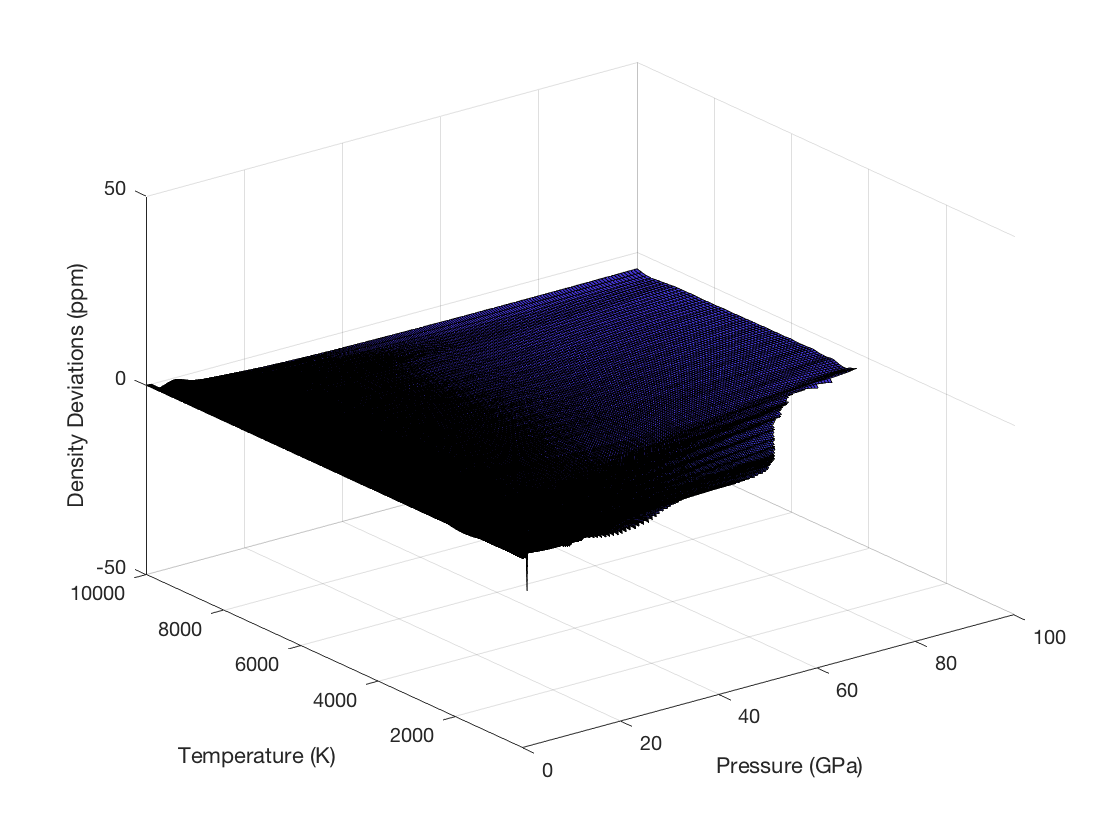


clf
therm_surf(PTd,eps+devsrho,results.mask,'Density Deviations (ppm)', ...
                     [0 1e5 240 1e4 -50 50])

Deviations of predicted densities from IAPWS-95 in ppm based on the integration of IAPWS-95 sound speeds. Density errors increase with pressure to about 3 ppm.  This error can be further reduced by using more steps in the integration. Errors at low temperatures can be reduced with more data and control points with temperature.  However, these results are considered adequately accurate.

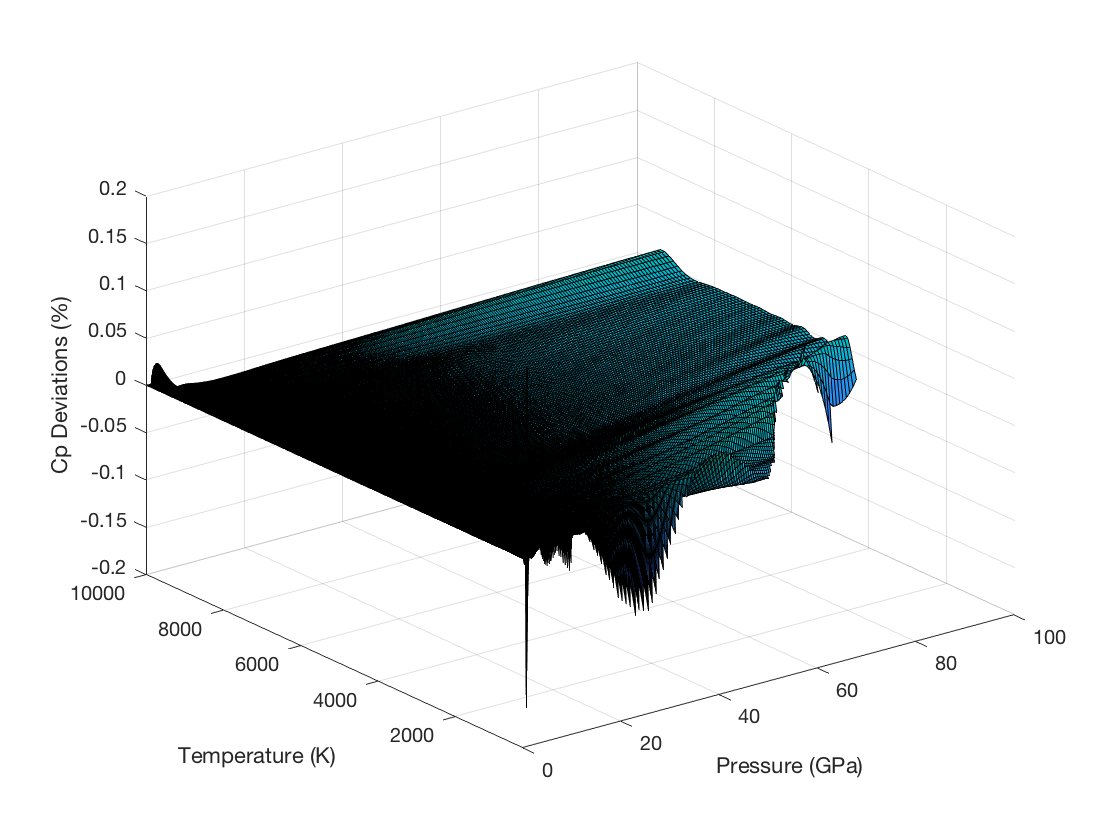

therm_surf(PTd,eps+devsCp,results.mask,'Cp Deviations (%)',[0 1e5 240 1e4 -.2 .2])

Deviations of specific heats from IAPWS-95 in percents based on the integration of IAPWS-95 sound speeds. Specific heats are recovered to a few hundredths of a percent except near edges in the metastable (with ice) regimes where errors increase to  ~ 0.1%.

The grid of EOS values are now converted to a LBF representation for Gibbs energy.

One can adjust the number of intervals for the local basis functions are needed (the number of control points determine the spacing of spline knots).  More control points/knots allow closer fitting, fewer points provides economy of representational size. The "size" (coefficient matrixes with ten thousand points) results in a relatively small digital file.Pc=[0.:10:90. logspace(2,log10(1e5),200)];

Tc=logspace(log10(240),log10(1.e4),150);
% avoid round off problems using the logspace function - enforce the value at
% the beginning and end
Tc(1)=240;Tc(end)=1.e4;
Pc=[ 0:5:98  logspace(2,5,150)];
PTc={Pc,Tc};
clear optionsG
optionsG.normflg=1;
optionsG.weight=[2e2 1e0];
optionsG.ordr=[6 6];
optionsG.lam=1e-6*[1 1];
optionsG.mask=results.mask;
optionsG.PTmc=PTc;
optionsG.normflg=1;

Here is the inversion for LBF representation: need to fiddle to get the best results,

sp_G_IAPWS=spgft(PTd,Gi(1,:),rhoi,Cpi,optionsG); 

How well does the LBF representation work? - compare to the original IAPWS output

outci=fnGval(sp_G_IAPWS,PTd);
devsrho=1e6*(rho-outci.rho)./rho;
devsCp=1e6*(Cp-outci.Cp)./Cp;
devsvel=1e2*(vel-outci.vel)./vel;
devsG=eps+(G-outci.G);

Make plots.  First show the EOS (density, Cp, sond speed, Gibbs Energy) over the entire PT regime, then focus on the low P and low T regime

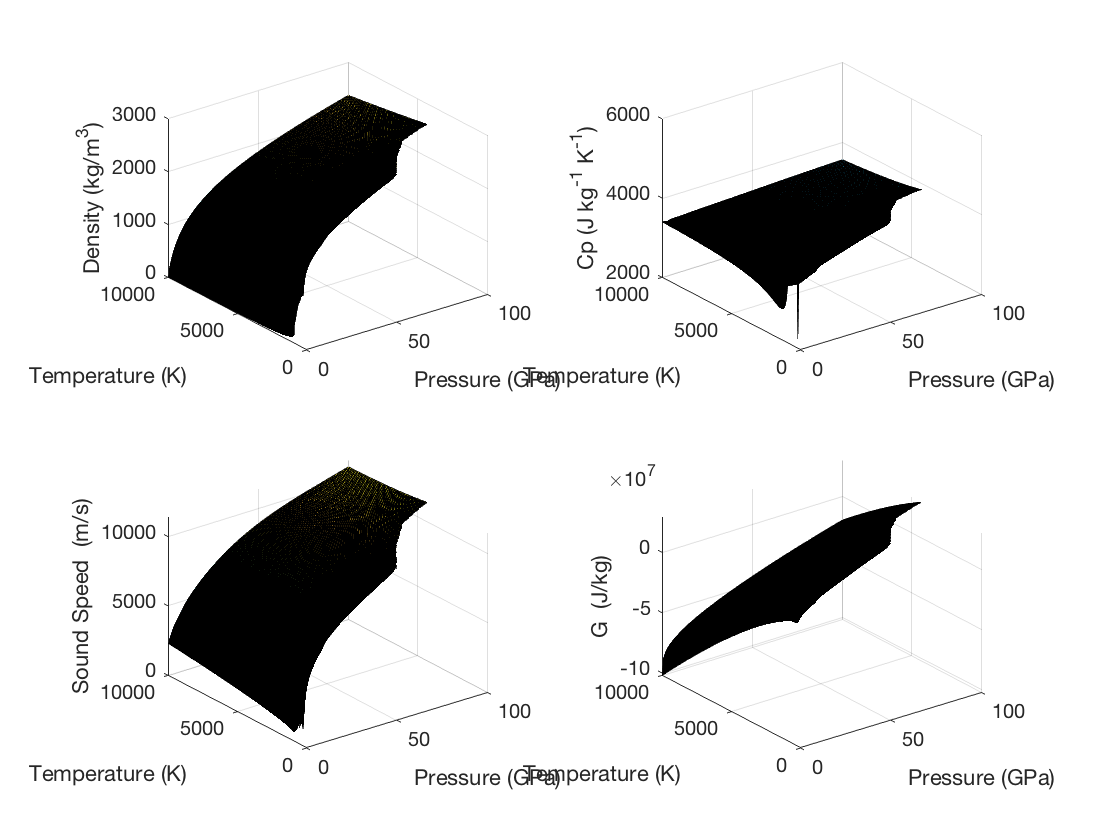

subplot(221)
therm_surf(PTd,outci.rho,results.mask,'Density (kg/m^3)')
subplot(222)
therm_surf(PTd,outci.Cp,results.mask,'Cp (J kg^-^1 K^-^1)') 
subplot(223)
therm_surf(PTd,outci.vel,results.mask,'Sound Speed  (m/s)') 
subplot(224)
therm_surf(PTd,outci.G,results.mask,'G  (J/kg)')

LBF representation of Gibbs energy based on integration of IAPWS-95 sound speeds to 100 GPa and 10,000 K.  Four panels give densities, specific heats, sound speeds, and Gibbs energy.

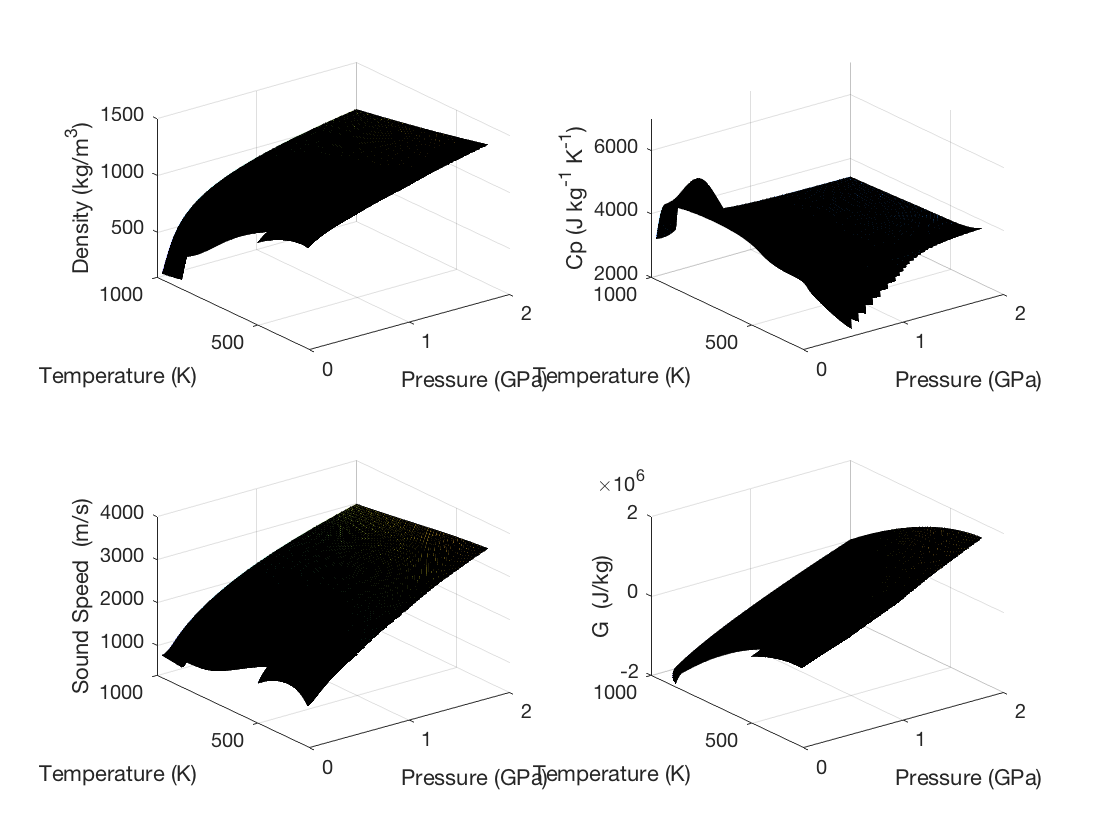

subplot(221)
therm_surf(PTd,outci.rho,results.mask,'Density (kg/m^3)',[0 2e3 240 1e3 100 1500])
subplot(222)
therm_surf(PTd,outci.Cp,results.mask,'Cp (J kg^-^1 K^-^1)',[0 2e3 240 1e3 2000 7000])
subplot(223)
therm_surf(PTd,outci.vel,results.mask,'Sound Speed  (m/s)',[0 2e3 240 1e3 300 4000])
subplot(224)
therm_surf(PTd,outci.G,results.mask,'G  (J/kg)',[0 2e3 240 1e3 -2e6 2e6])

LBF representation of Gibbs energy based on integration of IAPWS-95 sound speeds to 100 GPa and 10,000 K.  Here results are shown for P<1 GPa and T<1200 K.  Four panels give densities, specific heats, sound speeds, and Gibbs energy. The region near $T_c$is masked off in this analysis.

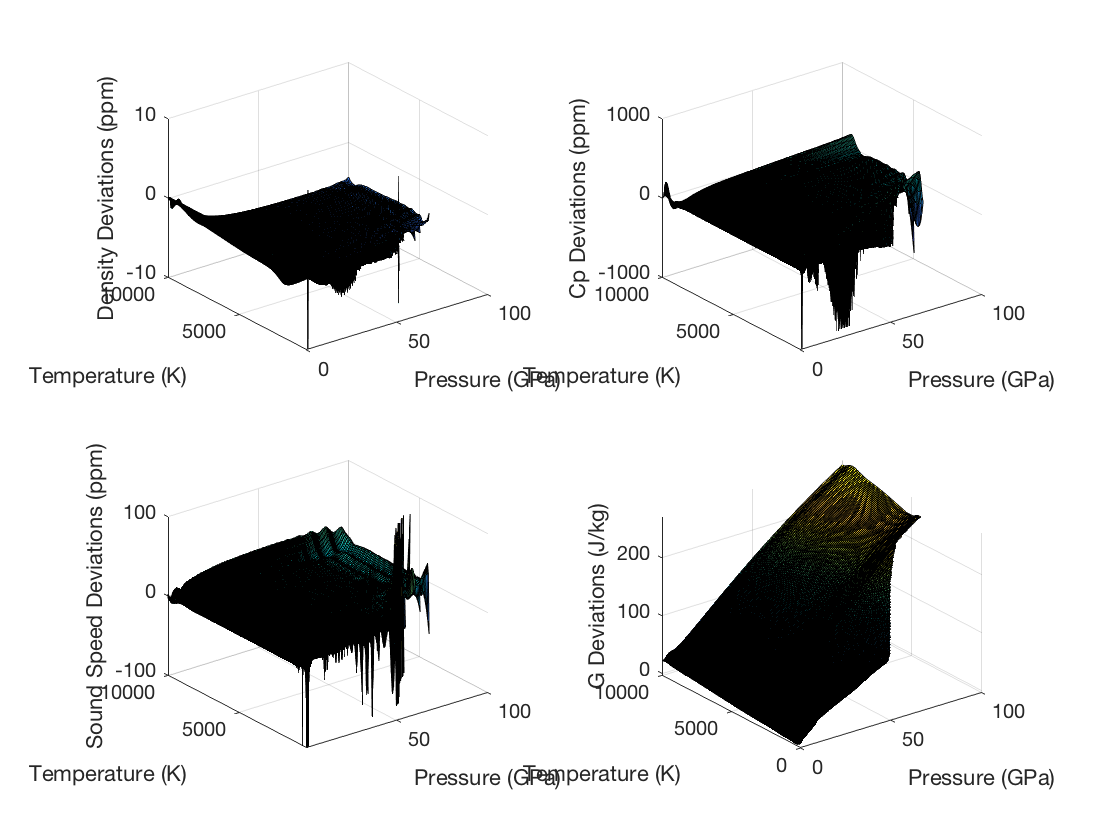

subplot(221)
therm_surf(PTd,eps+devsrho,results.mask,'Density Deviations (ppm)',...
              [0 1e5 240 1e4 -10 10])
subplot(222)
therm_surf(PTd,eps+devsCp,results.mask,'Cp Deviations (ppm)',...
                  [0 1e5 240 1e4 -1000 1000])
subplot(223)
therm_surf(PTd,1e4*devsvel,results.mask,'Sound Speed Deviations (ppm)',[.08e3 1e5 240 1e4 -100 100])%[.08e3 1e5 240 1e4 -1 1])%
                 %                 [.08e3 1e5 240 1e4 -2 2])
subplot(224)
therm_surf(PTd,devsG,results.mask,'G Deviations (J/kg)')        

Deviations from IAPWS-95  of the LBF representation of Gibbs energy based on integration of IAPWS-95 sound speeds to 100 GPa and 10,000 K.  Four panels give deviations of densities, specific heats, sound speeds, and Gibbs energy. Densities have a ~3 ppm systematic deviation at the highest pressures as a result of the numerical integration.  This gives a systematic error in Gibbs energy of ~300 J/kg at the highest pressures (a small fraction of the total energy).  Specific heats are mostly correct to ppm level with edge instabilities of ~0.1% (1000 ppm). Sound speeds are also recovered to ~10's of ppm with edge instabilities of ~1000 ppm =0.1%.

SECTION FOUR 

In the previous section, it was demonstrated that a grid of sound speeds from 240 K to 10,000 K and pressures to 100 GPa could be used to determine density/specific heats/Gibbs energy and that a LBF representation based on those values agreed with the reference EOS (IAPWS) to parts-per-million accuracy.

Since IAPWS does not adequately predict properties of water beyond about 1 GPa (see Abramson and Brown 2004 and others), in this section a modified LBF representation for water is created that better agree with high pressure sound speeds and shockwave measurements while remaining equal to IAPWS-95 below 1 GPa.

Corrections in percent ("cor" ) are chosen for sound speed deviations from IAPWS-95. A new LBF Gibbs energy representation is created that exactly agrees with IAPWS-95 below 1 GPa and diverges from IAPWS-95 at higher pressure in a fashion that better matches diamond-anvil cell sound speed and Hugoniot  measurements.  Here the correction is created as a grid of descrete points (three temperatures and 9 pressures) and  a tensor spline is run through the points to create a surface of sound speed deviations for all P and T in the space of the model.  This grid was developed as the "smallest" model for perturbations that provided an adequate fit to the sparse high pressure data. The perturbations are temperature independent and show three pressure regimes: a negative pressure derivative from 1 GPa to 5 GPa, a less negative pressure derivative from 5 GPa to 40 GPa, followed by a positive derivative above 40 GPa.  The choices for the perturbations represent "hand optimization" - an implementation of a non-linear optimization scheme is possible but has not yet been fully implemented.

p=[1e3 5e3 1e4   2e4 4e4 5e4 7.e4 8.5e4 1e5];
t=[240 5e3 1e4];
%     1e3    5e3           1e4         2e4           4e4     5e4      7e4         8.5e4     1e5
cor=[0 0 0; 3.3 3.3 3.3;  4. 4. 4.;    4.2 4.2 4.2; 4.5 4.5 4.5;  2 2 2;   -1 -1 -1;  -4 -4 -4;   -7 -7 -7 ];
 [pm,tm]=meshgrid(p,t);
 [pc,tc]=meshgrid(Pd(idhp),Td);
 corP=interp2(pm,tm,cor',pc,tc,'spline'); % this determines the perturbations at the grid points

 Create the surface (grid) of perturbed sound speeds

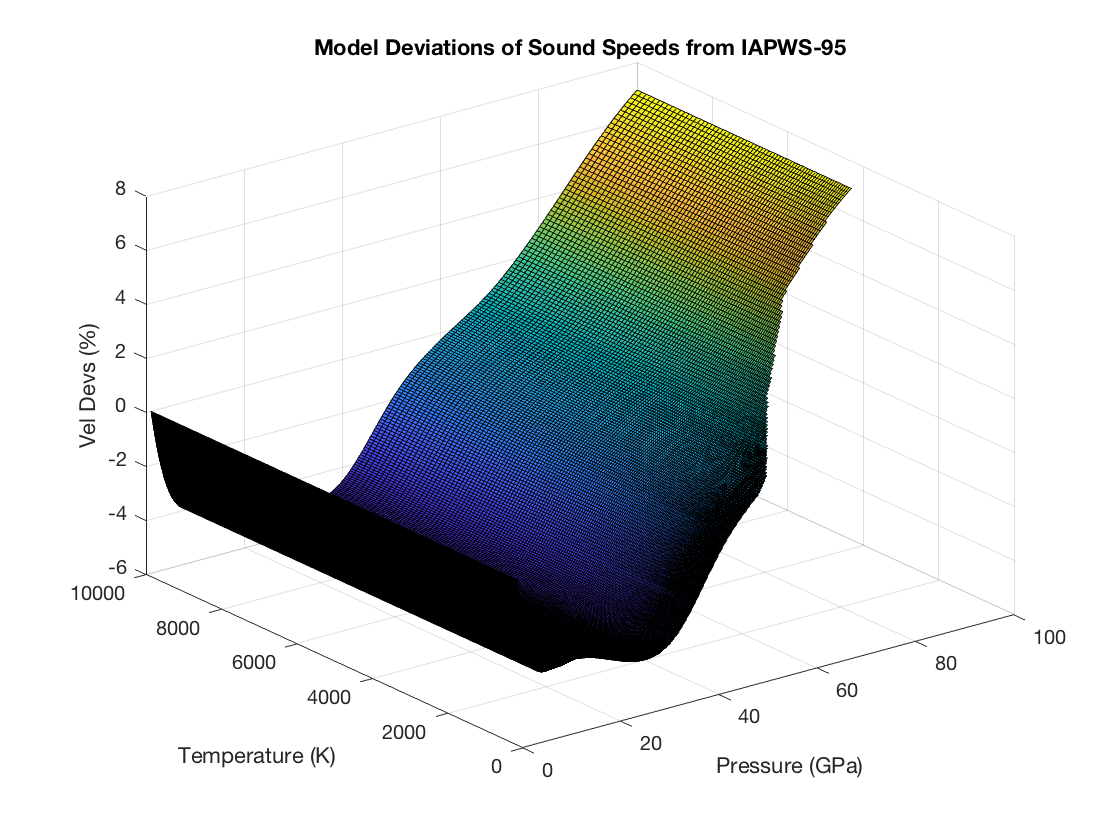

velp=vel;
mask=results.mask;
velp(idhp,:)=(1-1e-2*corP'.^1).*vel(idhp,:);
devs=1e2*mask.*(velp-vel)./vel;
subplot(111)
therm_surf(PTd,devs,mask,'Vel Devs (%)')
title('Model Deviations of Sound Speeds from IAPWS-95')

Integrate the perturbed sound speeds to determine densities, specific heats and Gibbs energies

Data.PT=PTdhp;
Data.rhoin=rho(idhp(1),:);
Data.Cpin=Cp(idhp(1),:);
Data.Go=G(idhp(1),:);
Data.vel=velp(idhp,:);
Data.mask=mask(idhp,:);
outm=eqst(Data,options_eqst1);

 Attach the EOS values below 1000 MPa

rhom=rho;
rhom(idhp,:)=outm.rho;
Cpm=Cp;
Cpm(idhp,:)=outm.Cp;
Gm=G;
Gm(idhp,:)=outm.G;


Make LBF version of the modified water EOS

sp_G_IAPWS_modified=spgft(PTd,Gm(1,:),rhom,Cpm,optionsG); 

How well does the modified LBF representation work? - compare to the original IAPWS output

outcm=fnGval(sp_G_IAPWS_modified,PTd);
devsrho=1e2*(rho-outcm.rho)./rho;
devsCp=1e2*(Cp-outcm.Cp)./Cp;
devsvel=1e2*(vel-outcm.vel)./vel;
devsG=(G-outcm.G);


Plot modified LBF representation over the entire range of P and T

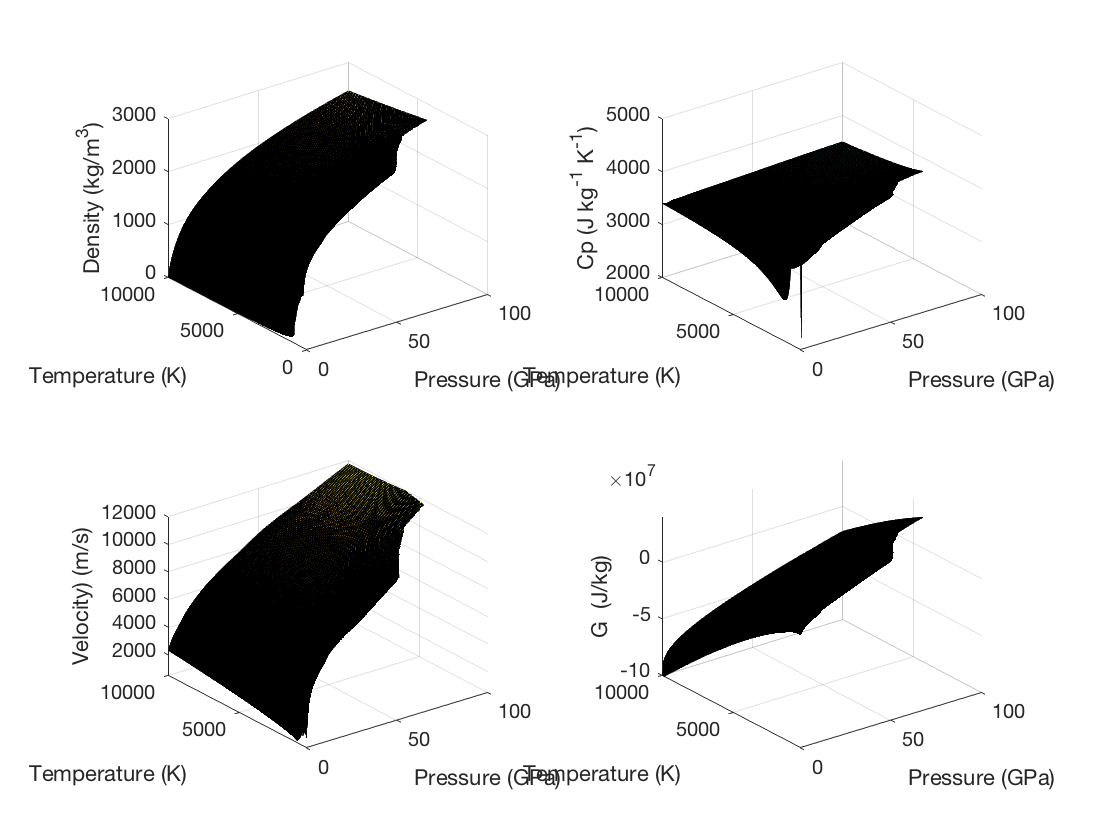

subplot(221)
therm_surf(PTd,outcm.rho,results.mask,'Density (kg/m^3)')
subplot(222)
therm_surf(PTd,outcm.Cp,results.mask,'Cp (J kg^-^1 K^-^1)',[0 1e5 240 1e4 2000 5000])
subplot(223)
therm_surf(PTd,outcm.vel,results.mask,'Velocity) (m/s)',[0 1e5 240 1e4 500 12000])
subplot(224)
therm_surf(PTd,outcm.G,results.mask,'G  (J/kg)',[0 1e5 240 1e4 -1e8 4e7])

Modified LBF representation for water.  Four panel show density, specific heat, sound speeds, and Gibbs energy.

Plot modified model in the low pressure regime

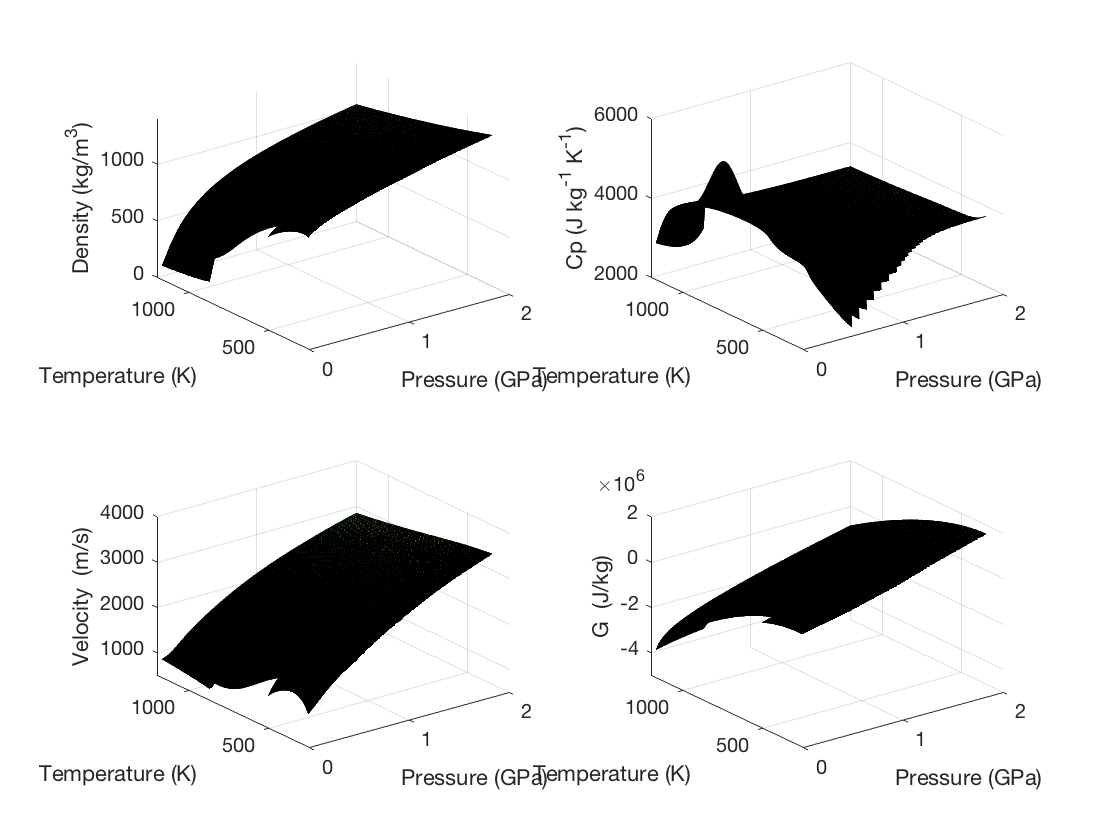

subplot(221)
therm_surf(PTd,outcm.rho,results.mask,'Density (kg/m^3)',[0 2e3 240 1200 00 1400])
subplot(222)
therm_surf(PTd,outcm.Cp,results.mask,'Cp (J kg^-^1 K^-^1)',[0 2e3 240 1200 2000 6000])
subplot(223)
therm_surf(PTd,outcm.vel,results.mask,'Velocity  (m/s)',[0 2e3 240 1200 500 4000])
subplot(224)
therm_surf(PTd,outcm.G,results.mask,'G  (J/kg)',[0 2e3 240 1200 -5e6 2e6])

Modified LBF representation in the low pressure and temperature regime.  

Plot deviations over entire range of P and T

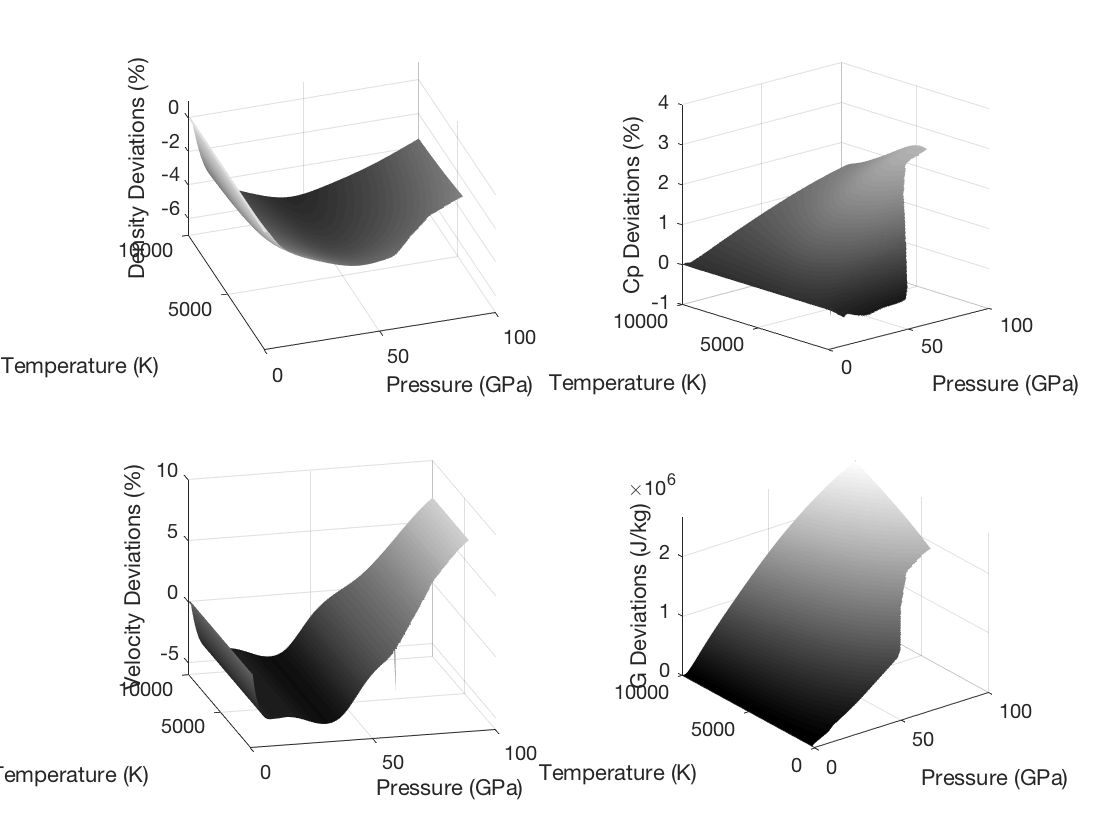

subplot(221)
therm_surf(PTd,devsrho,results.mask,'Density Deviations (%)',[0 1e5 240 1e4 -7 1])
shading flat
colormap gray
subplot(222)
therm_surf(PTd,devsCp,results.mask,'Cp Deviations (%)',[0 1e5 3e2 1e4 -1 4])
shading flat
colormap gray
subplot(223)
therm_surf(PTd,-devsvel,results.mask,'Velocity Deviations (%)',[0 1e5 240 1e4 -6 10])
shading flat
colormap gray
subplot(224)
therm_surf(PTd,devsG,results.mask,'G Deviations (J/kg)')
shading flat
colormap gray

subplot(2,2,1)
view([-18.3 42.0])
subplot(2,2,2)
view([-42.70 17.20])
subplot(2,2,3)
view([-14.3 21.2])

Deviations of predictions from IAPWS-95 based on the modified LBF representation for Gibbs energy.  Four panels give density, specific heat, sound speed and Gibbs energy deviations.  Deviations are in percent range for densities (~-6%), specific heats (~3%), and sound speeds (~10%). Gibbs energy deviations are as large as O(${10}^6$) J/kg.

Plot model and deviations in low pressure regime:

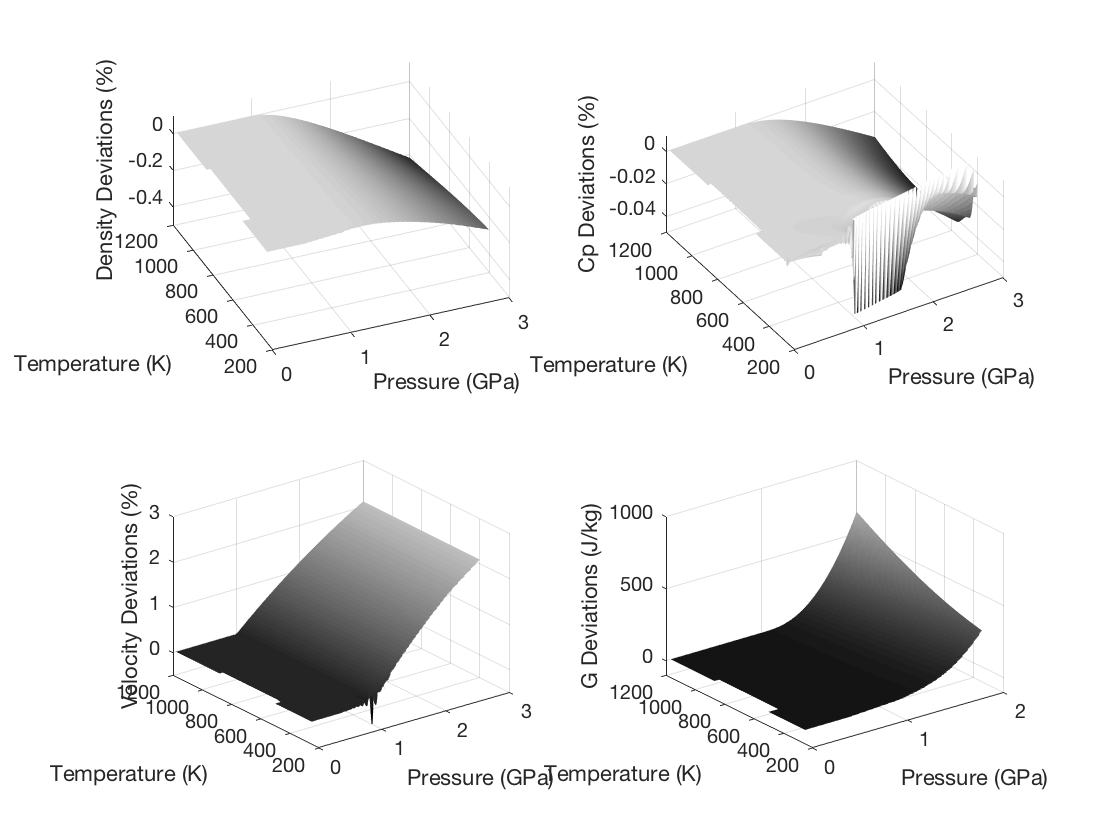


subplot(221)
therm_surf(PTd,devsrho,results.mask,'Density Deviations (%)',[0 3e3 200 1200 -.5 .1])
view([-18.700 30.800])
shading flat
colormap gray
subplot(222)
therm_surf(PTd,devsCp,results.mask,'Cp Deviations (%)',[0 3e3 200 1200 -.05 .01])
shading flat
colormap gray
subplot(223)
therm_surf(PTd,devsvel,results.mask,'Velocity Deviations (%)',[0 3e3 200 1200 -0.5 3])
shading flat
colormap gray
subplot(224)
therm_surf(PTd,devsG,results.mask,'G Deviations (J/kg)',[0 2e3 200 1200 -.1e3 1e3])
shading flat
colormap gray

subplot(2,2,2)
view([-33.100 50.800])

subplot(2,2,1)
view([-22.70 50.80])

subplot(2,2,2)
view([-31.500 54.800])

Deviations of predictions from IAPWS-95 based on the modified LBF representation for Gibbs energy in a low pressure and low temperature regime.  Four panels give density, specific heat, sound speed and Gibbs energy deviations.  Deviations are a few tenths of a percent for densities and a few hundreths of a percent for specific heats, sound speeds vary by ~2% at 3 GPa. Gibbs energy deviations are  O(${10}^3$) J/kg. Some instability of specific heat predictions at low T are apparent (<0.2%) along the melting phase bondary.  Note that by construction, the modified LBF representation agrees exactly with IAPWS-95 below 1 GPa. 

In this section, the modified LBF represetation is compared to high pressure (shock wave and sound speeds) measurements.

load WaterDataSets
load IAPWS_sp_strct
% Lyzenga data
%      P    rho  T (K)
dataL=[48.9 2.26 3280
       58.5  2.34 3830
       61.9  2.36 4090
       71.0 2.41 4480
       80   2.47 5270];
% Kormer data
%       P    T
dataK=[30  1895
       30  2079
       31.9  1895
       31.9  2079
       39.2  2447
       39.2  2553];

ph=logspace(3,log10(8.5e4),30);
[rhoh,Th,Eh]=CalcWaterHug(sp_IAPWS,ph);
[rhoh2,Th2,Eh2]=CalcWaterHug(sp_G_IAPWS_modified,ph);
np=10;
pc=linspace(ph(1),ph(end),np);
dz=water.data{5}.z;
dz(1:4)=dz(1:4)/1e1;
%

Plot of Hugoniot data and predictions from the modified model

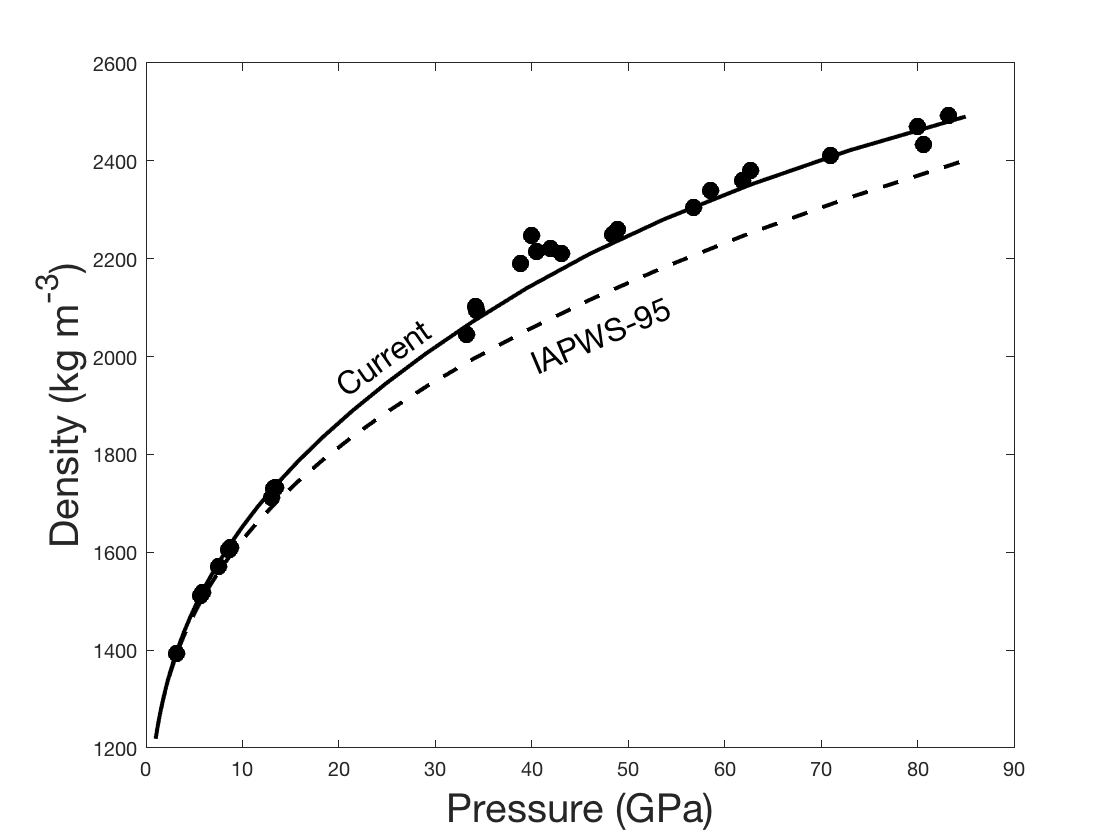

subplot(111)
plot(ph/1e3,rhoh,'k--','LineWidth',2);
hold on
plot(ph/1e3,rhoh2,'k-','LineWidth',2)
plot(water.data{5}.P,1e3*water.data{5}.z,'ko','MarkerFaceColor','k','MarkerSize',8)
hold off

xlabel('Pressure (GPa)','FontSize',20)
ylabel('Density (kg m^-^3)','FontSize',20)
text(40,1985,'IAPWS-95','FontSize',16,'Rotation',23)
text(20,1935,'Current','FontSize',16,'Rotation',35)

Hugoniot densities vs pressure for water. Measurements are black circles. IAPWS-95 (dashed) and the modified LBF representation (solid) are shown. The choice of perturbations for sound speeds provide a closer match to the measurements than the base IAPWS-95 formulation

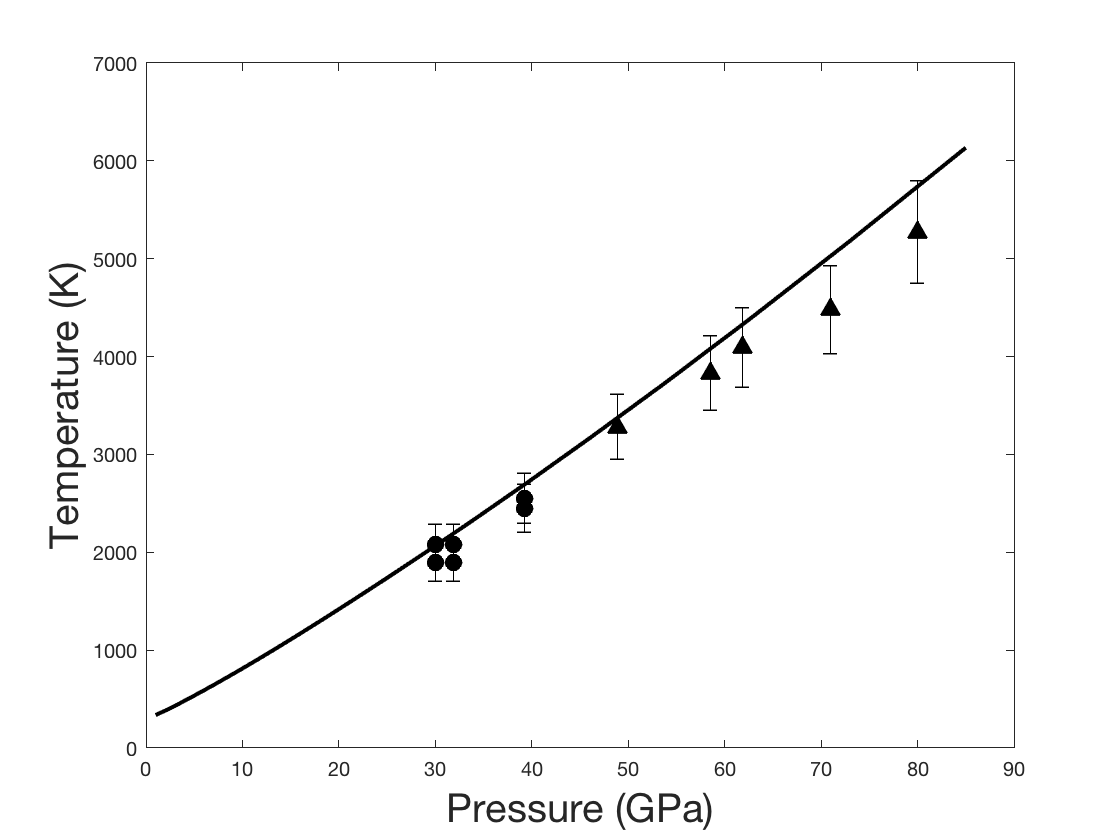

subplot(111)
 plot(ph/1e3,Th,'k-','LineWidth',2);
 hold on
  errorbar(dataK(:,1),dataK(:,2),0.1*dataK(:,2),'ko','MarkerFaceColor','k','MarkerSize',8)
  errorbar(dataL(:,1),dataL(:,3),0.1*dataL(:,3),'k^','MarkerFaceColor','k','MarkerSize',8)
 hold off

xlabel('Pressure (GPa)','FontSize',20)
ylabel('Temperature (K)','FontSize',20)

Hugoniot temperatures as a function of pressure. Black filled circles are measurements, the solid line is the LBF representation prediction. The model is adequately predicting Hugoniot temperatures.

In this section, sound speed predictions of the modified LBF representation are compared with diamond anvil measurements.

outiapws=fnIAPWSval(PTd);
outc=fnGval(sp_G_IAPWS_modified,PTd);

Calculate deviations between Decremps et al and the modified EOS

Ts=water.data{2}.T;
Ps=water.data{2}.P;
vels=1e3*water.data{2}.z;
id723=find(Ts==723);
id673=find(Ts==673);
id573=find(Ts==573);
id473=find(Ts==473);
id400=find(Ts==400);


Per Abramson and Brown (figure 1),  a systematic difference in the temperature calibration of pressure determinations exists between UW and the group in France. This difference in calibration, based on the figure in Abramson and Brown is applied below. The issue is not which group has the correct calibration. Rather,this places both data sets in the same frame of reference.

Ps(id723)=Ps(id723)+.12;
Ps(id673)=Ps(id673)+.09;
Ps(id573)=Ps(id573)+.06; 
Ps(id473)=Ps(id473)+.03;
Ps(id400)=Ps(id400)+.02;
outcs=fnGval(sp_G_IAPWS_modified,[1e3*Ps(:) Ts(:)]);
velcs=outcs.vel;
devs=1e2*(vels-velcs)./velcs;

Calculate deviations between Abramson and Brown and the modified EOS

Pab=water.data{1}.P;
Tab=water.data{1}.T;
velab=1e3*water.data{1}.z;
outab=fnGval(sp_G_IAPWS_modified,[1e3*Pab(:) Tab(:)]);
velcab=outab.vel;
devab=1e2*(velab-velcab)./velcab;

Calculate deviations between Ashara et al and the modified EOS

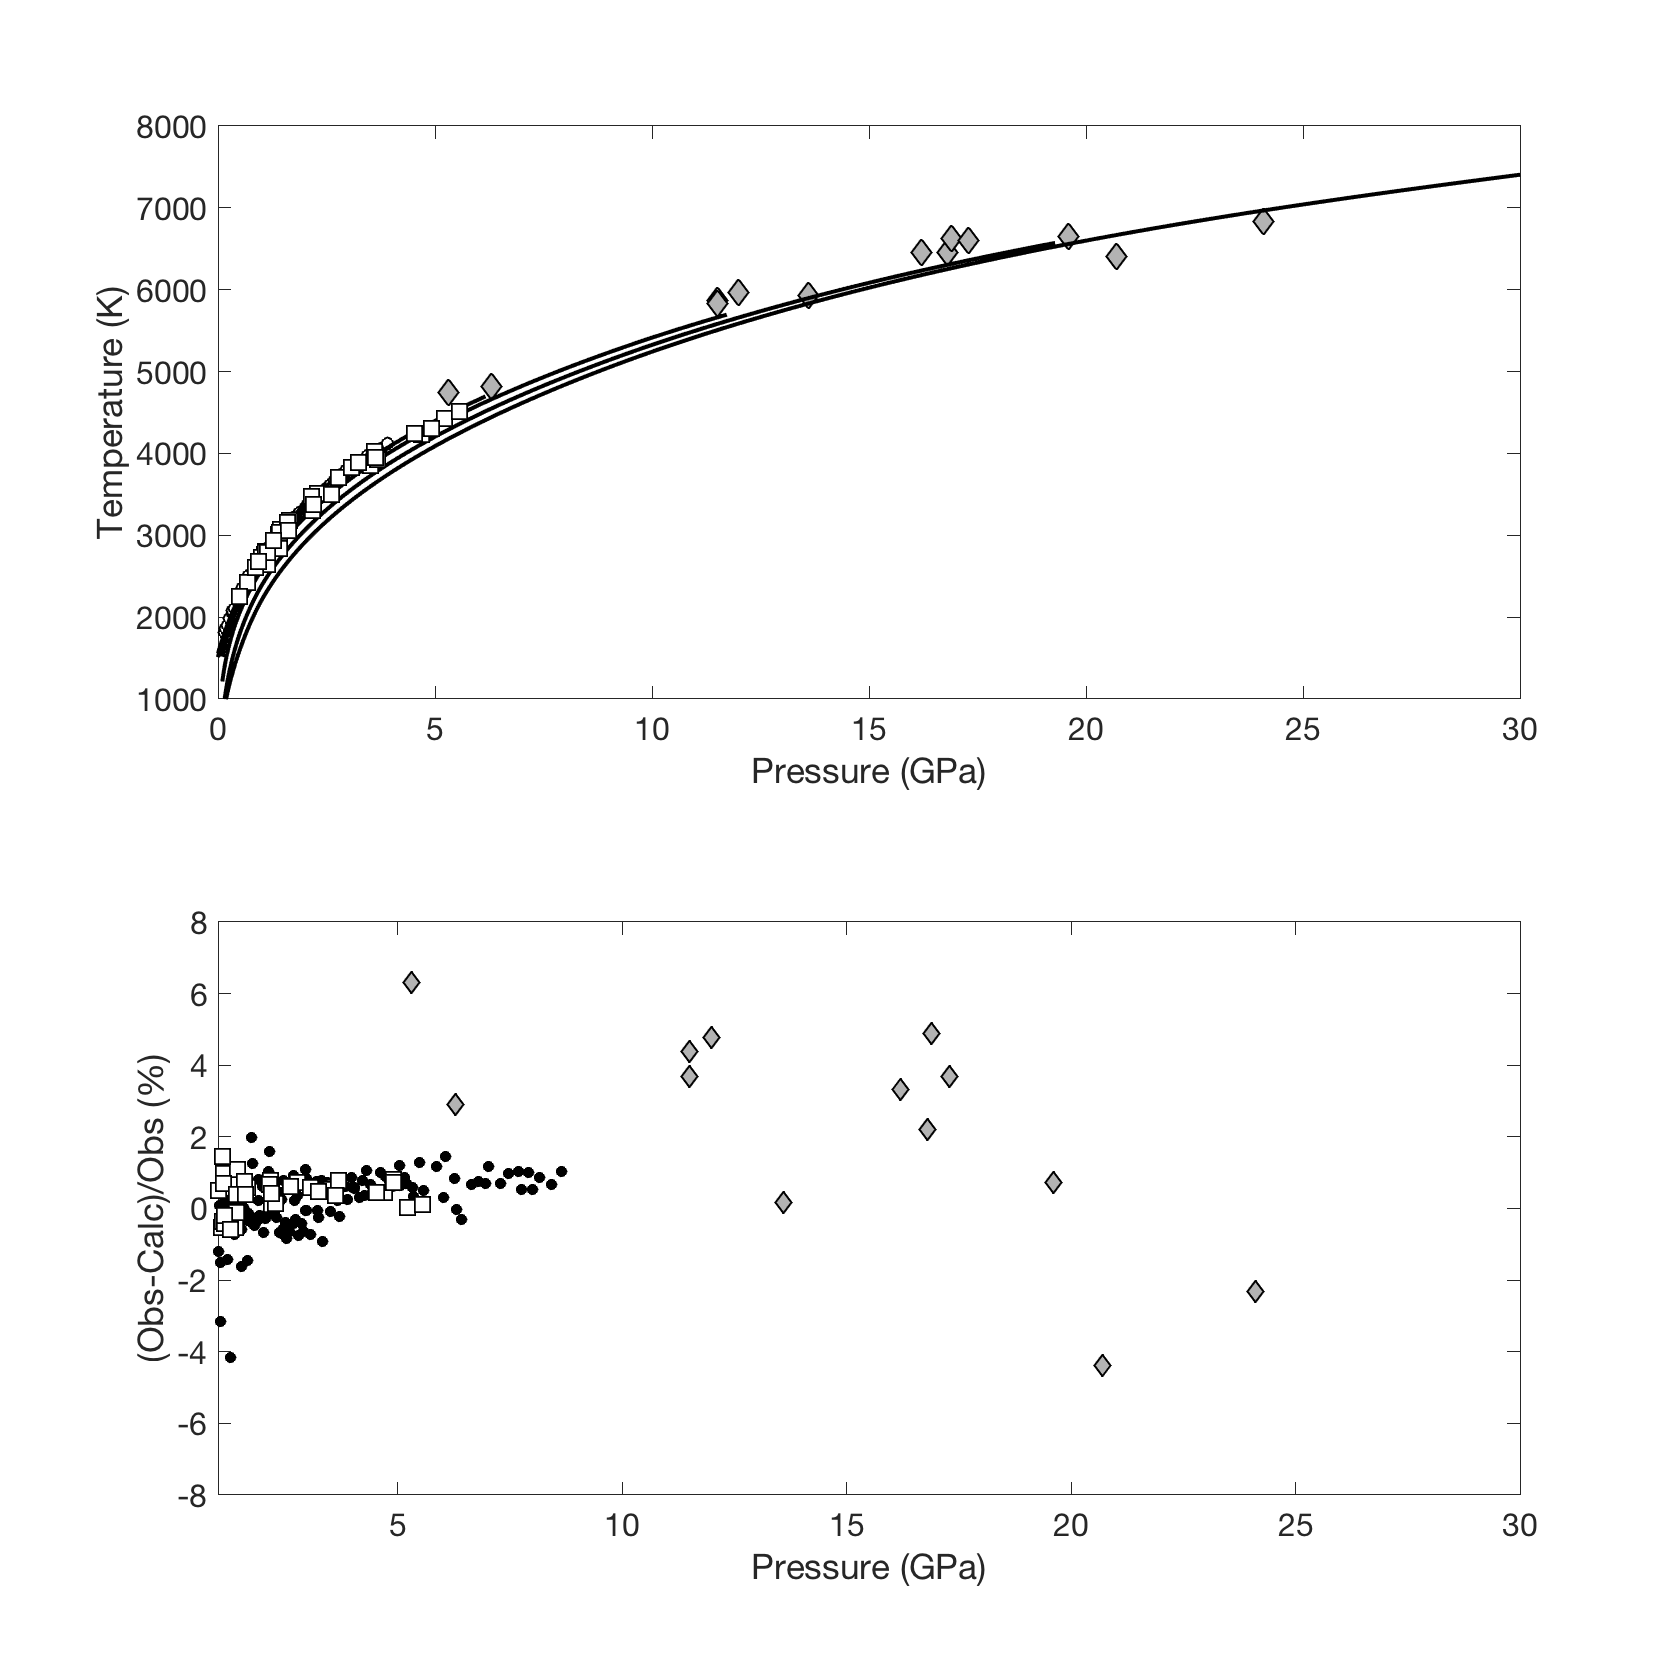

Pa=water.data{3}.P;
Ta=water.data{3}.T;
vela=1e3*water.data{3}.z;
outa=fnGval(sp_G_IAPWS_modified,[1e3*Pa(:) Ta(:)]);
velca=outa.vel;
deva=1e2*(vela-velca)./velca;
scrsz=get(0,'ScreenSize');
figsz=[1 .8*scrsz(4) 2*scrsz(3)/4 .8*scrsz(4)];
h=figure('Name','Water Sound Speeds','Position',figsz);
%
sb1=subplot(211);
Pp=PTd{1}/1e3; % use GPa here
%plot sound speeds
plot(Ps(id400),vels(id400),'ko','MarkerSize',6,'MarkerFaceColor','w')
hold on
plot(Pa,vela,'kd','MarkerSize',10,'MarkerFaceColor',[.7 .7 .7])
plot(Pp,mask(:,[27 39 60 76 100 120])'.*outc.vel(:,[27 39 60 76 100 120])','k','LineWidth',2)
plot(Pab,velab,'ks','MarkerSize',10,'MarkerFaceColor','w')
hold off
xlabel('Pressure (GPa)','Fontsize',20)
ylabel('Temperature (K)','Fontsize',20)
axis([0 30 1000 8000])
set(sb1,'FontSize',16);

sb2=subplot(212);
plot(Ps,devs,'ko','MarkerSize',5,'MarkerFaceColor','k')
hold on
plot(Pa,deva,'kd','MarkerSize',8,'MarkerFaceColor',[.7 .7 .7])
plot(Pab,devab,'ks','MarkerSize',10,'MarkerFaceColor','w')
axis([1 30 -8 8])
hold off
xlabel('Pressure (GPa)','FontSize',20)
ylabel('(Obs-Calc)/Obs (%)','FontSize',20)
set(sb2,'FontSize',16)

Sound speeds for water at high pressure. Upper panel:  Symbols are diamond anvil measurements (open square: Abramson and Brown, Black filled circles: Decremps et al., gray diamonds: Ashara et al.).  Solid lines (selected isotherms from 300 K to 1100 K) are predictions based on the modified LBF representation for Gibbs energy. Lower panel: Deviations of measurements (same symbols) from prediction of LBF representation.